**Francisco Moyet Vargas**

**Exercise 1:**

(a) Surface plot:

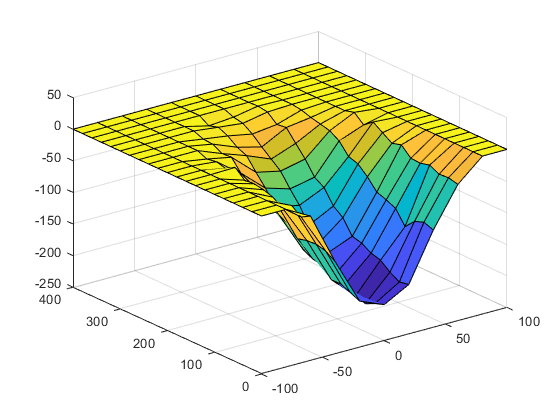

load('reservoir.mat');
surf(X,Y,Z)

Part(b): computing the volume:


a = 200;
b = 400;
func = @Q;
Volume = -integral2(func,-100,100,0,b,"Method","iterated")

Volume = 2.7093e+06

function [q] = Q(x,y)
load('reservoir.mat');
[x1,y1] = meshgrid(X,Y);
NewZ=interp2(x1,y1,Z,x,y);
q=NewZ;
end

function [p] = pr(x,y)
rho = 1000;
g=9.8;
p = rho*g*Q(x,y);
end
